Aufgabe 1:

Zeigen Sie anhand der zeitdiskreten harmonischen Schwingung x(kT) = cos(2*pi*f*s*kT), dass die beiden Signale

x̂ ( kT ) = ( h * x )( kT ) Faltung von h mit x, MATLAB-Befehle 'conv' oder 'filter'

und x(kT – NT/2)

im eingeschwungenen Zustand (k >= N) eine gegenseitige Phasenverschiebung von phase = 90°

aufweisen. Variieren Sie dazu auch die Frequenz fs , um die Frequenzunabhängigkeit der

Phasenverschiebung zu zeigen. Oszillografieren Sie beide Signale gleichzeitig und messen

Sie die Phasenverschiebung. Verwenden Sie den M-File Hilbert_Sinus.m.

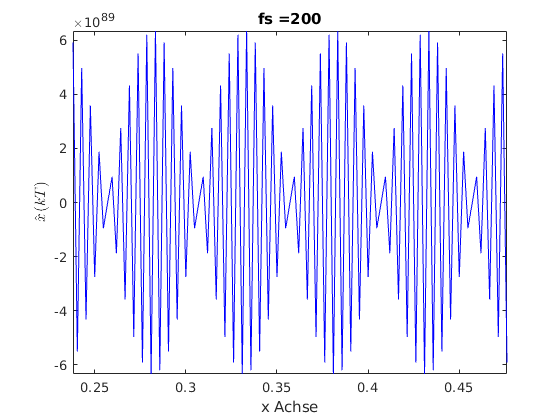

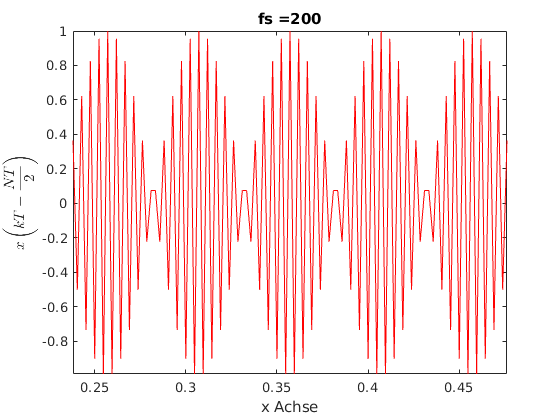

PhDiff = 1.5708

PhGrad = 90.0000

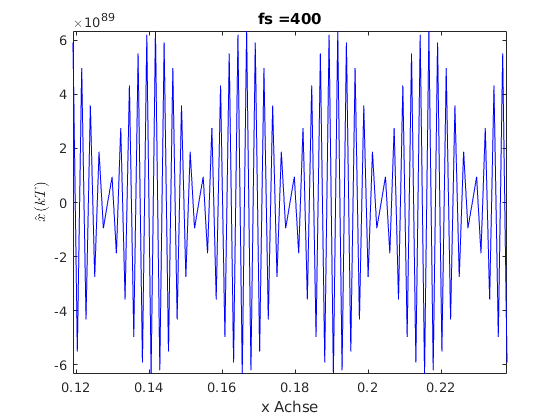

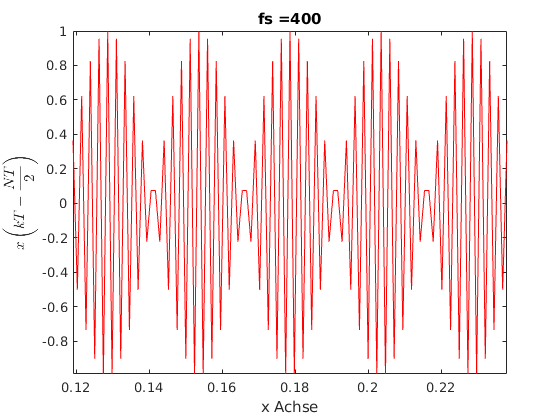

PhDiff = 1.5708

PhGrad = 90.0000

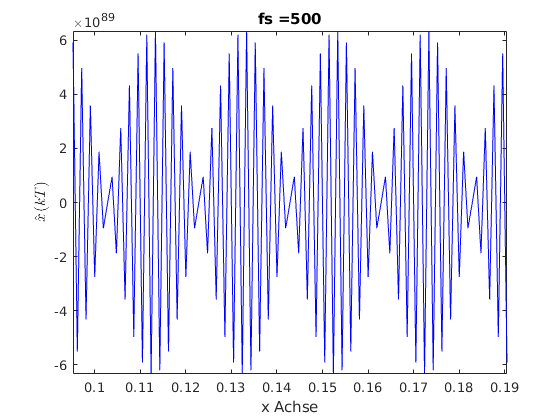

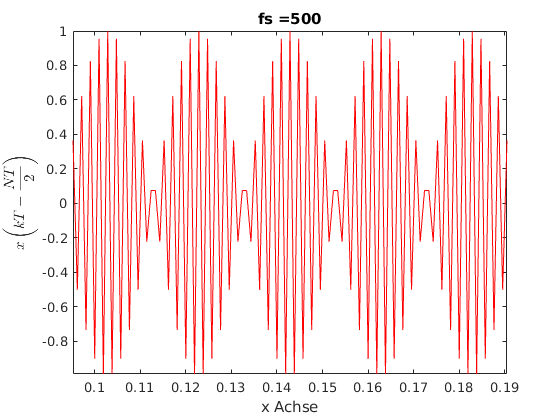

PhDiff = 1.5708

PhGrad = 90.0000

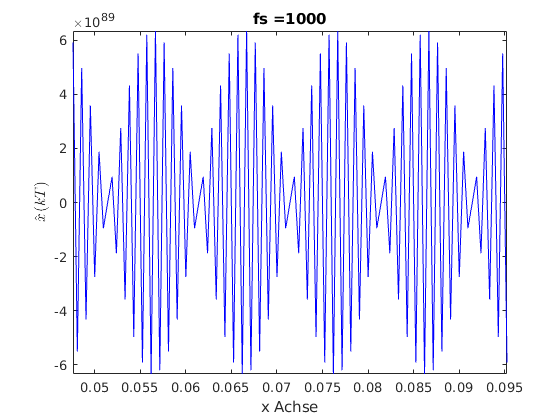

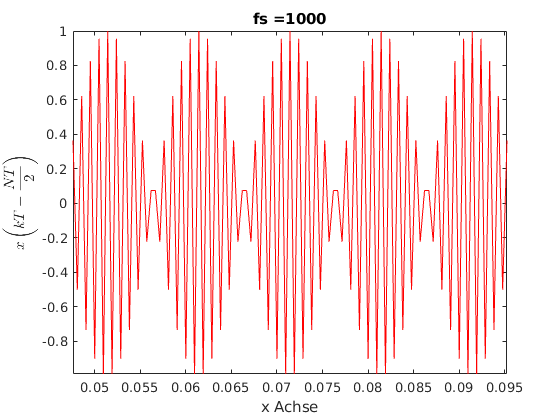

PhDiff = 1.5708

PhGrad = 90.0000

N=90;                                           %Grad
k=1:999;                                         
h = remez(90,[0.02 0.098],[1,1],'Hilbert');     %Hilbert-Transformator

for fs = [200, 400, 500, 1000]                  %verschiedene Frequenzen 
    fT = 2.1*fs;                                %Abtastfrequenz
    T = 1/fT;                                   %Abtastzeitdauer                                
    kT = k*T;                                   %Abtastwerte 
    x = cos(2*pi*fs*kT);                        %harmonische Schwingung
    xdach=conv(h,x);                            %Berechnung von xdach durch die Faltung von x und h
    xv  = [zeros(1,N/2) x(1,1:length(x)-N/2)];  %Zeitverschiebung des Signals x um die Länge N/2
    
    figure;                                     %Plot der funktionen xdach und x
    plot( kT((N+10):(N+110)), xdach((N+10):(N+110)), '-b');
    title('fs =' + string(fs))
    ylabel('$$\hat{x}\left(kT\right)$$', 'Interpreter',"latex");
    xlabel('x Achse');
    axis tight;
    
    figure;
    plot(kT((N+10):(N+110)), xv((N+10):(N+110)), '-r');
    title('fs =' + string(fs))
    ylabel('$$x\left(kT-\frac{NT}{2}\right)$$', 'Interpreter',"latex");
    xlabel('x Achse');
    axis tight;
    
    XV = fft(xv((N+10):(N+110)));               %Berechnung des Spektrums von xv
    XDACH = fft(xdach((N+10):(N+110)));         %Berechnung des Spektrums von xdach
    
    [~, ind1] = max(abs(XDACH));
    [~, ind2] = max(abs(XV));
    
    PhDiff = abs(angle(XDACH(ind1)) - angle(XV(ind2)))  %Berechnung der Phasendifferenz
    PhGrad = PhDiff *180/pi
end;

Verwenden Sie nun anstelle der zeitdiskreten harmonischen Schwingung x(kT) = cos(2*pi*f*s*kT)

ein Sweepsignal (M-File Hilbert_Sweep.m).

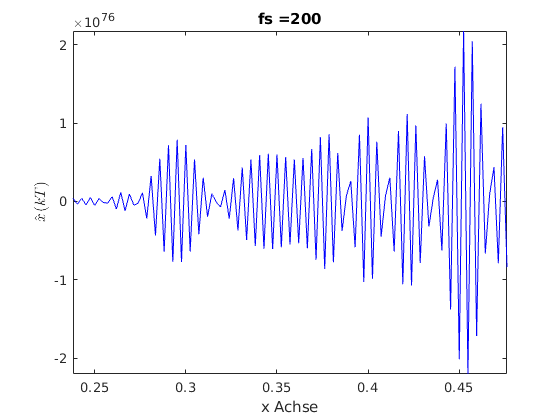

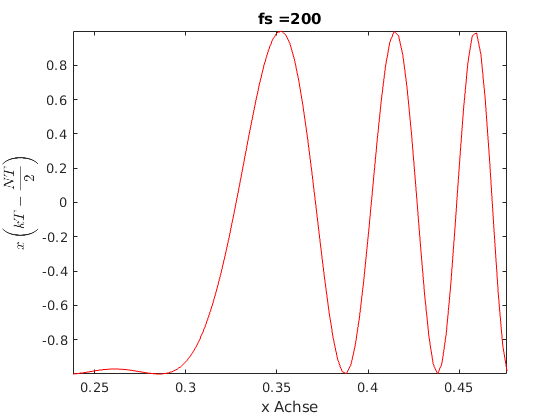

PhDiff = 2.3313

PhGrad = 133.5731

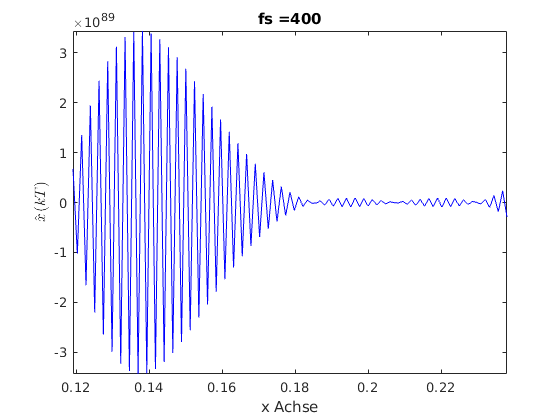

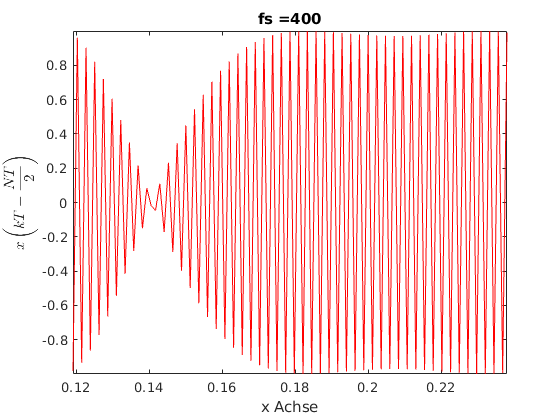

PhDiff = 1.5491

PhGrad = 88.7553

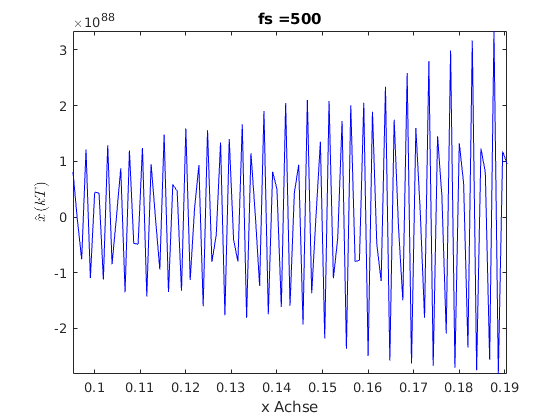

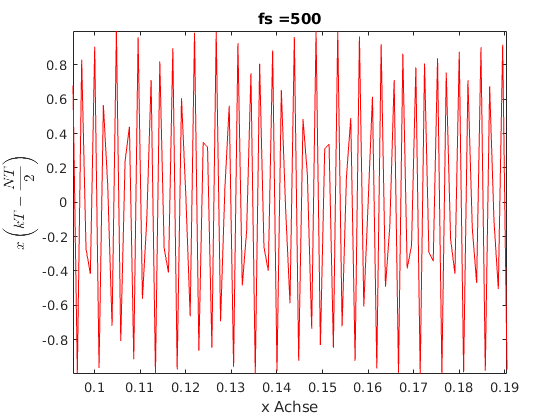

PhDiff = 1.7680

PhGrad = 101.2961

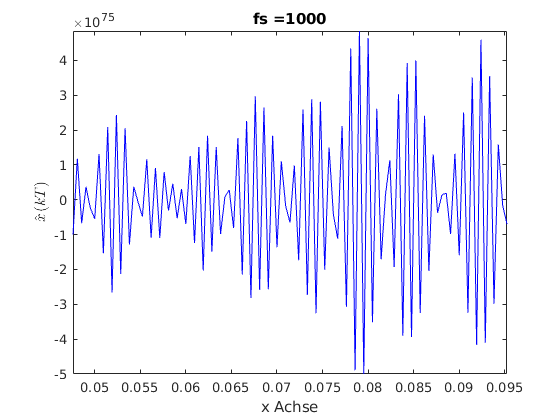

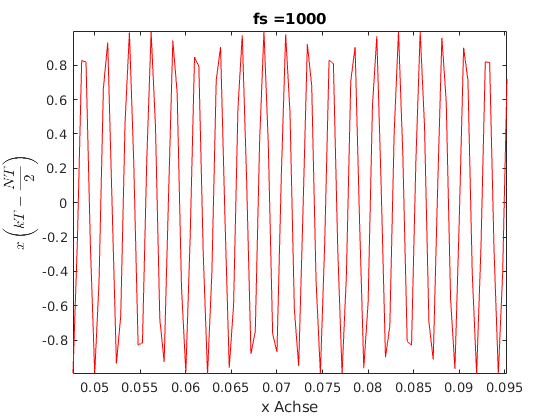

PhDiff = 0.2953

PhGrad = 16.9204

N=90;                                           %Grad
k=1:999;
h = remez(90,[0.02 0.098],[1,1],'Hilbert');     %Hilbert-Transformator

for fs = [200, 400, 500, 1000]                  %verschiedene Frequenzen 
    fT = 2.1*fs;                                %Abtastfrequenz
    T = 1/fT;                                   %Abtastzeitdauer 
    kT = k*T;                                   %Abtastwerte
    x=chirp((1:20*fT)/fT,400,20,3000);          %Eingangssignal
    xdach=conv(h,x);                            %Berechnung von xdach durch die Faltung von x und h
    xv  = [zeros(1,N/2) x(1,1:length(x)-N/2)];  %Zeitverschiebung des Signals x um die Länge N/2
    
    figure;                                     %Plot der funktionen xdach und x
    plot( kT((N+10):(N+110)), xdach((N+10):(N+110)), '-b');
    title('fs =' + string(fs))
    ylabel('$$\hat{x}\left(kT\right)$$', 'Interpreter',"latex");
    xlabel('x Achse');
    axis tight;
    
    figure;
    plot(kT((N+10):(N+110)), xv((N+10):(N+110)), '-r');
    title('fs =' + string(fs))
    ylabel('$$x\left(kT-\frac{NT}{2}\right)$$', 'Interpreter',"latex");
    xlabel('x Achse');
    axis tight;
    
    XV = fft(xv((N+10):(N+110)));               %Berechnung des Spektrums von xv
    XDACH = fft(xdach((N+10):(N+110)));         %Berechnung des Spektrums von xdach
    
    [~, ind1] = max(abs(XDACH));
    [~, ind2] = max(abs(XV));
    
    PhDiff = abs(angle(XDACH(ind1)) - angle(XV(ind2)))
    PhGrad = PhDiff *180/pi
end;

Legen Sie ein Sprachsignal an den Eingang des Hilbert-Transformators und geben Sie das

Ausgangssignal über die Soundkarte aus. Wird die Sprachverständlichkeit durch den Hilbert-

Transformator beeinträchtigt? Wiederholen Sie die Aufgabe auch mit anderen Audiosignalen

(M-File Hilbert_Audio.m).

h = remez(90,[0.02 0.098],[1,1],'Hilbert');         %Hilbert-Transformator

%[y, fT] = audioread('sprachsinus.wav');            %unterschiedliche .wav
%[y, fT] = audioread('Histcode_mod.wav');           %Dateien als
%[y, fT] = audioread('MATLAB_chirp.wav');           %Eingangssignal
[y, fT] = audioread('MATLAB_gong.wav');
%[y, fT] = audioread('MATLAB_handel.wav');
%[y, fT] = audioread('MATLAB_laughter.wav');
%[y, fT] = audioread('MATLAB_splat.wav');
%[y, fT] = audioread('MATLAB_train.wav');
%[y, fT] = audioread('Rauschen.wav');

%soundsc(y,fT);
soundsc(conv(h,y),fT);      %Ausgabe der Faltung des Hilbert-Transfomator und des 
% Eingangssignals über die Soundkarte